# ENAE432 - Homework 5

Vai Srivastava

% Clear history
clear;
clc;

## Problem 1

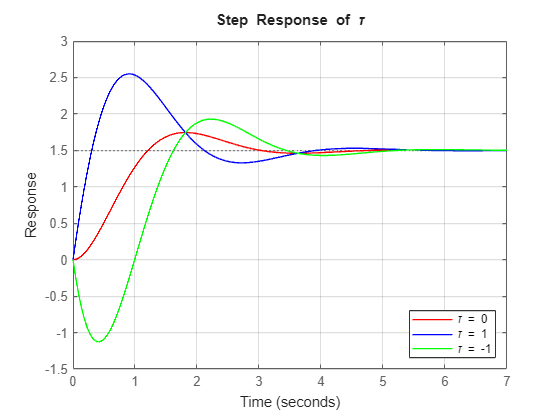

s = tf('s');
tau = [0, 1, -1];
colors = ['r', 'b', 'g'];
denom = s^2 + 2*s + 4;

figure; 
hold on;
for j = 1:length(tau)
    G = 6 * (tau(j) * s + 1) / denom;
    step(G,colors(j));
end

grid on;
legend('\tau = 0', '\tau = 1', '\tau = -1', Location="southeast");
title('Step Response of \tau');
xlabel('Time');
ylabel('Response');
hold off;

## Problem 2

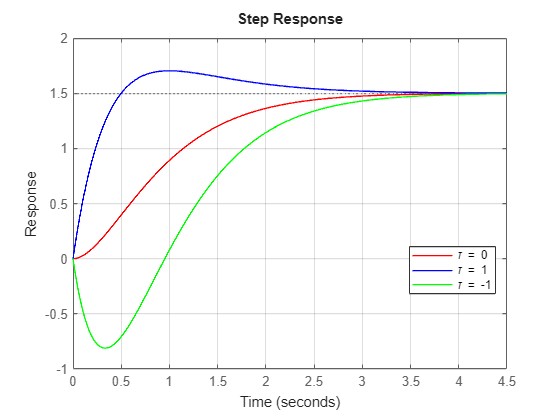

denom = s^2 + 4*s + 4;

figure;
hold on;
for j = 1:length(tau)
    G = 6 * (tau(j) * s + 1) / denom;
    step(G,colors(j));
end

grid on;
legend('\tau = 0', '\tau = 1', '\tau = -1', 'Location', 'best');
title('Step Response');
xlabel('Time');
ylabel('Response');
hold off;

## Problem 3

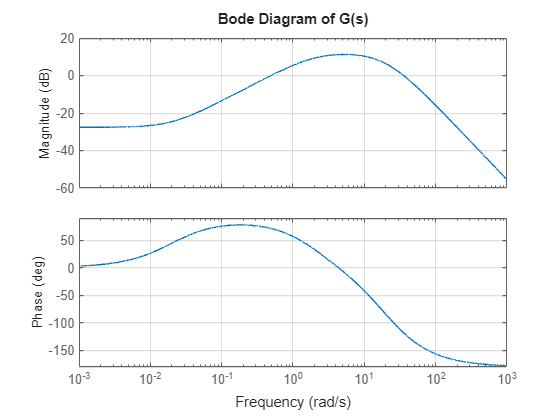

G = (5000 * (s + 0.02))/(3 * (2 + s) * (20 + s)^2);

w = logspace(-3, 3, 10000); 
figure; 
bode(G,w);
grid on;
title('Bode Diagram of G(s)');

## Problem 4

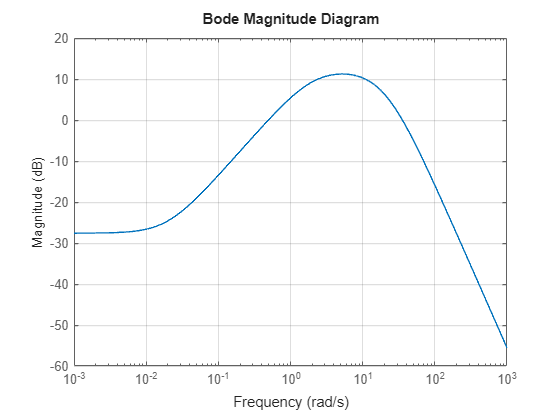

Error using print (line 90)
There was a problem while generating the output: Requested print job was cancelled or stopped.

f1 = figure;
bodemag(G);
grid on;
orient landscape;
title('Bode Magnitude Diagram');
print(f1);